# **    Proyecto Final: Despacho económico para una microrred **

**Camilo Guerrero, Brayan Benavies**

**Maestría en Ingenieria Electrónica (MaIE)**

**   Universidad de Nariño**

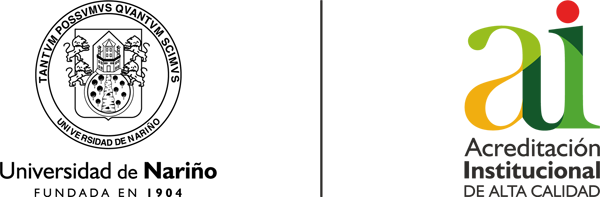

## Problema

Encontrar el despacho económico para la microrred.

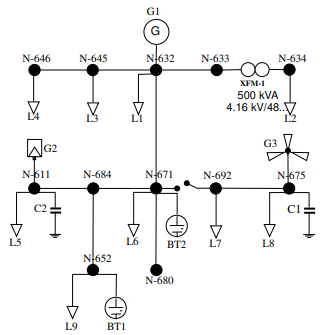  

             
$$P_{\max } \left\lbrack \textrm{kW}\right\rbrack$$
         
$$P_{\min } \left\lbrack \textrm{kW}\right\rbrack$$


$G_1$            2000                200          Generador Diesel

$G_2$            1213                  0            Generador Fotovoltáico

$G_3$              717                  1            Generador Eólico

$BT_1$            600               -600          Banco de Baterias 1

$BT_2$            400               -400          Banco de Baterias 2

% Definir los Parametros de los dispositivos
clearvars;
clc;

G1Max = 2000; G1Min = 200;           %GENERADOR DIESEL 
G2Max = 1213; G2Min = 0;             %GENERADOR FOTOVOLTAICO 
G3Max = 717;  G3Min = 1;             %GENERADOR EOLICO 
BT1Max = 600;   BT1Min = -600;       %BANCO DE BATERIAS1
BT2Max = 400;   BT2Min = -400;       %BANCO DE BATERIAS2
n_ch  = 1;                            % Eficiencia de carga
n_dis = 1;                            % Eficiencia de descarga
S_max1 = 5*BT1Max; S_min1 = 0.1*S_max1;  % Limites de carga/descarga 1
S_max2 = 5*BT2Max; S_min2 = 0.1*S_max2;  % Limites de carga/descarga 2
S1 = S_max1*0.5; S2 = S_max2*0.5;    % Estado de carga inicial del 50%


## Demanda

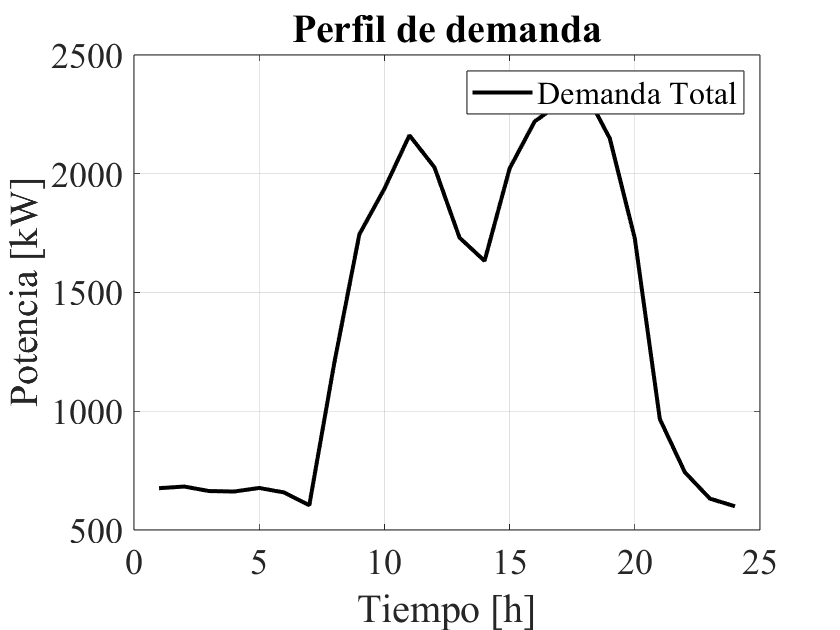

%load('PLT.mat');

%PLT= PL;
PL=[676,683,664,662,677,658,604,1204,1745,1937,2162,2027,1731,1633,2022,2220,2296,2349,2149,1728,967,743,632,600];
figure
T=1:24;
plot(T,PL,'k','LineWidth',2)
xlabel('Tiempo [h]','fontsize',20)
ylabel('Potencia [kW]','fontsize',20)
title('Perfil de demanda','fontsize',20)
set(gca,'Fontname','Times New Roman','FontSize',18)
legend('Demanda Total')
grid on

## Límites de Generación

PGDMax = G1Max*ones(1,24);   % LIMITES DE GENERACION PARA G1 DIESEL
PGDMin = G1Min*ones(1,24);

%load('G2PV.mat')             % Curva de Potencia para G2 FOTOVOLTAICO
%load('G3EOLICO.mat')         % Curva de Potencia para G3 EOLICO
%aux=G2PV./max(G2PV);
%PpvMax = rho*G2PV;      % LIMITES DE GENERACION PARA G2 FOTOVOLTAICO

irrad=[0,0,0,0,0,0,86,293,563,949,1213,1135,1118,1108,863,766,546,227,6,0,0,0,0,0]*0.7;
rho=1.2;  % Factor ajuste
PpvMax=rho*irrad;
PpvMin = G2Min*ones(1,24);

%PGEOMax = G3EOLICO;          % LIMITES DE GENERACION PARA G3 EOLICO
PGEOMax=[141,156,1,154,140,127,101,174,496,717,706,591,436,351,275,226,200,138,111,149,201,229,177,165];

%PGEOMin = G3Min*G3EOLICO;
PGEOMin=G3Min*PGEOMax;

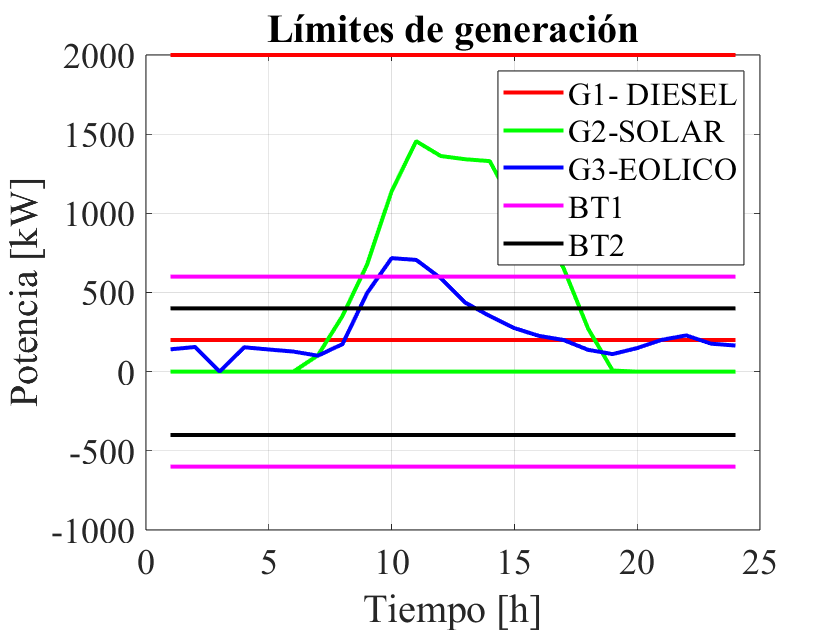


PBT1Max = BT1Max*ones(1,24); % LIMITES DE GENERACION PARA BT1
PBT1Min = BT1Min*ones(1,24);

PBT2Max = BT2Max*ones(1,24); % LIMITES DE GENERACION PARA BT2
PBT2Min = BT2Min*ones(1,24);

figure
T = 1:24;
plot(T,PGDMax,'r', T,PGDMin,'r',T,PpvMax,'g',T,PpvMin,'g',T,PGEOMax,'b',T,PGEOMin,'b',T,PBT1Max,'m', T,PBT1Min,'m',T,PBT2Max,'k', T,PBT2Min,'k' ,'LineWidth',2); hold on
xlabel('Tiempo [h]','fontsize',20);ylabel('Potencia [kW]','fontsize',20);legend('G1- DIESEL','','G2-SOLAR','','G3-EOLICO','','BT1','','BT2')
title('Límites de generación','fontsize',20);set(gca,'Fontname','Times New Roman','FontSize',18);grid on;

## Función de Costos 

%Coeficientes de costos 
%  [G1-Diésel G2-Fotovoltaico G3-EOLICO BT1 BT2]
aa=[  1.53        0.0            0.0    0.0 0.0];
bb=[ 1150.5       400            500    600 700];
cc=[ 104.44      28.77          35.90   0.0 0.0];

%Funcion de costos

Cpower = @(p) ((aa(1)*p(1).^2)+bb(1)*p(1)+cc(1)) + (bb(4)*p(2)) + (bb(5)*p(3)) +  (0*p(4)) + (0*p(5)); 
%              --------------G1----------------   ----PBT1dis---  ---PBT2dis--   ---BT1ch-- ---PBT2ch--

## Restricciones 

**Balance de potencia**

Busca que en cada instante de gestión el despacho supla toda la demanda


$$P_{\left\lbrace \mathrm{GD}\right\rbrace } +P_{\left\lbrace \mathrm{BT1}\right\rbrace } +P_{\left\lbrace \mathrm{BT2}\right\rbrace } =P_L -\left(P_{\left\lbrace \mathrm{PV}\right\rbrace } +P_{\left\lbrace \mathrm{EO}\right\rbrace } \right)$$


** Límites de generación**

- Para el Generador diésel    

             
$$P_{\min } \le P\left(k\right)\le P_{\max }$$
 

- El BT se puede optimizar considerando lo siguiente

            $P_{\textrm{BT}} =n_{\textrm{ch}} P_{\textrm{ch}} +\frac{P_{\textrm{dis}} }{n_{\textrm{dis}} }$,         (1)

donde, $n_{\textrm{ch}}$, $n_{\textrm{dis}}$, $P_{\textrm{ch}}$  y $P_{\textrm{dis}}$ son la eficiencia de carga,  la eficiencia de descarga, la potencia de carga y la potencia de descarga de la BT.  Por lo tanto los límites se definen por separado para carga y descarga

            
$$P_{\min } \le P_{\textrm{ch}} \left(k\right)\le 0$$


            
$$0\le P_{\textrm{dis}} \left(k\right)\le P_{\max }$$


**Estado de carga del banco de baterias (SOC)**

$S_{\min } \le S\left(k\right)\le S_{\max }$                  (2)

El estado de carga actual $S\left(k\right)$ se calcula apartir del estado de carga anterior $S\left(k-1\right)$ y de la pontencia en la bateria $P_{\textrm{BT}}$ descrita en (1)


$$S\left(k\right)=S\left(k-1\right)-P_{\textrm{BT}}$$
 

$S\left(k\right)=S\left(k-1\right)-\left(n_{\textrm{ch}} P_{\textrm{ch}} +\frac{P_{\textrm{dis}} }{n_{\textrm{dis}} }\right)$   (3)

Finalmente, a partir de (2) y (3), los límites para el estado de carga establecen las siguientes restriciones de desigualdad


$${-n}_{\textrm{ch}} P_{\textrm{ch}} -\frac{P_{\textrm{dis}} }{n_{\textrm{dis}} }$$

$$\le S_{\max } -$$

$$S\left(k-1\right)$$


$n_{\textrm{ch}} P_{\textrm{ch}} +\frac{P_{\textrm{dis}} }{n_{\textrm{dis}} }$$\le {-S}_{\min }$+$S\left(k-1\right)$

% RESTRICCIÓN DE IGUALDAD

%     [G1  PBT1dis  PBT2dis  PBT1ch PBT2ch]
Aeq = [1   1/n_dis  1/n_dis   n_ch   n_ch ];

beq = PL - PpvMax - PGEOMax; %DUDA 
%---------------------------------------------
%RESTRICCIÓN DE DESIGUADAD

% [G1 PBT1dis  PBT2dis PBT1ch PBT2ch]
A=[0 -1/n_dis    0     -n_ch    0;      %BT1
   0  1/n_dis    0      n_ch    0;      %BT1
   0    0    -1/n_dis    0    -n_ch;    %BT2
   0    0     1/n_dis    0     n_ch];   %BT2

b=[S_max1-S1; -S_min1+S1;S_max2-S2;-S_min2+S2];
%---------------------------------------------
%LIMITES INFERIOR Y SUPERIOR 
nonlcon = [];                                 %No existen restricciones no lineales
lb=[G1Min   0         0     BT1Min   BT2Min]; %Limite inferior
ub=[G1Max BT1Max    BT2Max    0         0  ]; %Limite superior

## Ciclo de Optimización

K = 24;                 % Horas de gestión
P = zeros(K, 5);        % Potencia generada por cada dispositivo
fval = zeros(K, 1);     % Costo de la potencia generada en cada instante de gestión
x0 = [0 0 0 0 0];       % Condiciones iniciales
SOC1 =  [S1; zeros(K, 1)]; % Estado de carga para BT1
SOC2 = [S2; zeros(K, 1)]; % Estado de carga para BT2
options = optimoptions('fmincon', 'Display', 'iter', 'Algorithm','sqp'); %MÉTODO DE SOLUCIÓN
BT1_status=zeros(1,24);
BT2_status=zeros(1,24);

tic
for i = 1:K   
    [P(i, :), fval(i)] = fmincon(Cpower, x0, A, b, Aeq, beq(i), lb, ub, nonlcon, options);
    SOC1(i+1) =  SOC1(i)  - n_ch * P(i,4) - (P(i, 2) / n_dis); % Estado de carga de BT1
    SOC2(i+1) = SOC2(i) - n_ch * P(i,5) - (P(i,3) / n_dis);  % Estado de carga de BT2
    b = [S_max1 - SOC1(i+1); -S_min1 + SOC1(i+1); S_max2 - SOC2(i+1); -S_min2 + SOC2(i+1)];

     % Actualizar estado de carga/descarga
    if P(i, 2)+P(i,4) > 0
        BT1_status(i) = -1; % Descargando
    elseif P(i, 2)+P(i,4) < 0
        BT1_status(i) = 1; % Cargando
    else
        BT1_status(i) = 0; % Inactivo
    end
    
    if P(i, 3)+P(i,5) > 0
        BT2_status(i) = -1; % Descargando
    elseif P(i, 5)+P(i,5) < 0
        BT2_status(i) = 1; % Cargando
    else
        BT2_status(i) = 0; % Inactivo
    end

end

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to satisfy the bounds.
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           6    2.914044e+05     3.350e+02     1.000e+00     0.000e+00     1.763e+03  
    1          12    5.041545e+05     1.137e-13     1.000e+00     2.472e+02     2.175e+02  
    2          18    4.988043e+05     1.137e-13     1.000e+00     7.566e+01     6.173e+01  
    3          24    4.924044e+05     0.000e+00     1.000e+00     9.051e+01     1.477e+01  
    4          30    4.924044e+05     0.000e+00     1.000e+00     4.552e-14     4.547e-13  

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


toc

Elapsed time is 1.592194 seconds.


## Resultados

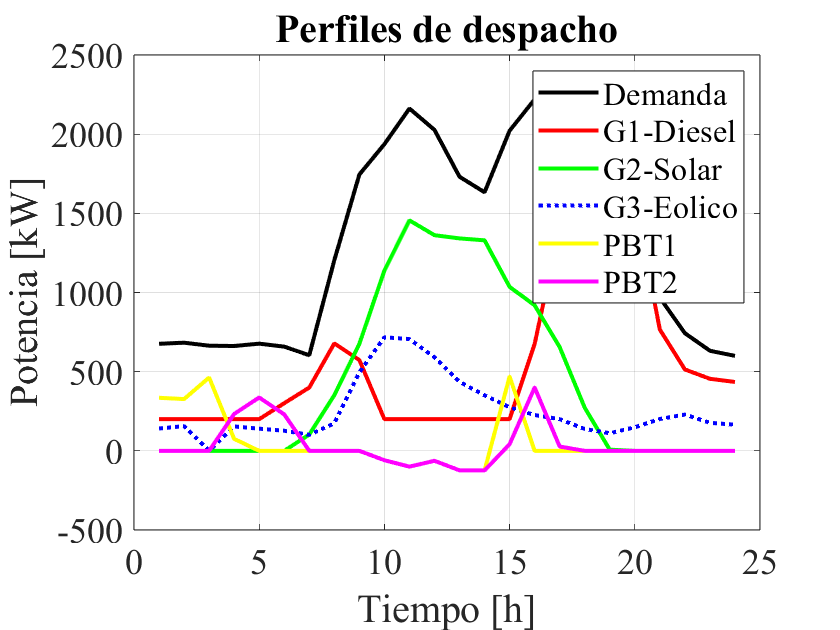

PGD   = P(:,1);     % Potencia despachada por el generador Diésel
Pdis1 = P(:,2);     % Potencia de descarga del BT1
Pdis2 = P(:,3);     % Potencia de descarga del BT2
Pch1  = P(:,4);     % Potencia de carga del BT1
Pch2  = P(:,5);     % Potencia de carga del BT2
PBT1  = Pch1+Pdis1; % Potencia TOTAL BT1
PBT2  = Pch2+Pdis2; % Potencia TOTAL BT2

figure %Perfiles de Despacho
T = 1:K;
plot(T,PL,'k',T,PGD,'r', T,PpvMax,'g', T,PGEOMax,'b:',T,PBT1,'y',T,PBT2,'m','LineWidth',2); 
xlabel('Tiempo [h]','fontsize',20);ylabel('Potencia [kW]','fontsize',20);legend('Demanda','G1-Diesel','G2-Solar','G3-Eolico','PBT1','PBT2')
title('Perfiles de despacho','fontsize',20);set(gca,'Fontname','Times New Roman','FontSize',18);grid on

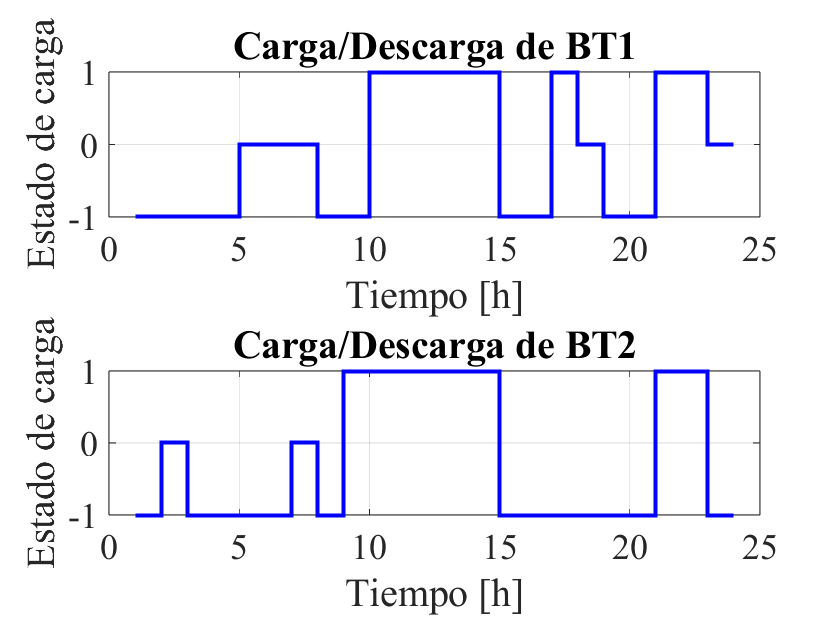

figure
T=1:24;
subplot(2,1,1)
stairs(T,BT1_status,'b','LineWidth',2);
xlabel('Tiempo [h]','fontsize',20);ylabel('Estado de carga','fontsize',20);
title('Carga/Descarga de BT1','fontsize',20);set(gca,'Fontname','Times New Roman','FontSize',18);grid on



subplot(2,1,2)
stairs(T,BT2_status,'b','LineWidth',2);
xlabel('Tiempo [h]','fontsize',20);ylabel('Estado de carga','fontsize',20);
title('Carga/Descarga de BT2','fontsize',20);set(gca,'Fontname','Times New Roman','FontSize',18);grid on;

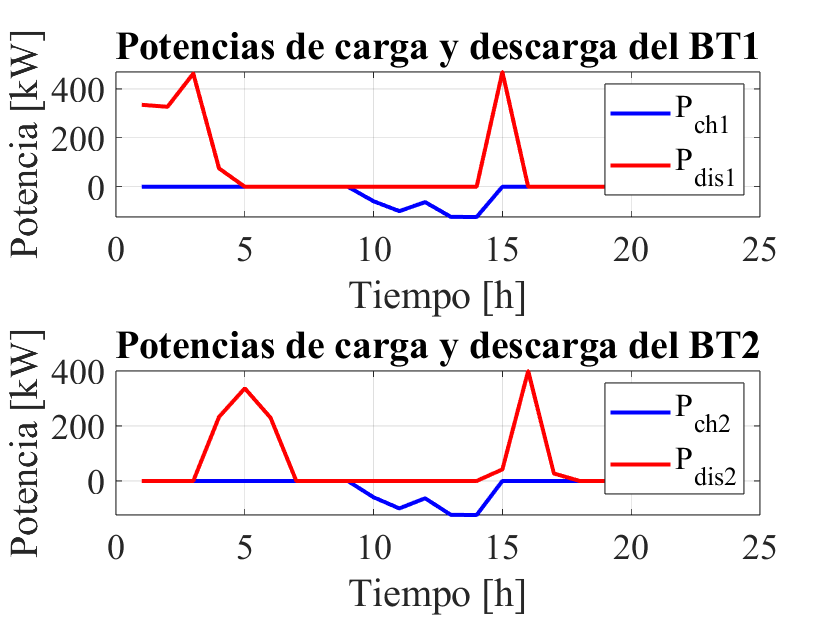

figure %Carga y descarga BT1
T = 1:24;
subplot(2,1,1)
plot(T,Pch1,'b',T,Pdis1,'r','LineWidth',2); 
xlabel('Tiempo [h]','fontsize',20);ylabel('Potencia [kW]','fontsize',20);legend('P_{ch1}','P_{dis1}')
title('Potencias de carga y descarga del BT1','fontsize',20);set(gca,'Fontname','Times New Roman','FontSize',18);grid on

%figure %Carga y descarga de BT2
subplot(2,1,2)
plot(T,Pch2,'b',T,Pdis2,'r','LineWidth',2); 
xlabel('Tiempo [h]','fontsize',20);ylabel('Potencia [kW]','fontsize',20);legend('P_{ch2}','P_{dis2}')
title('Potencias de carga y descarga del BT2','fontsize',20);set(gca,'Fontname','Times New Roman','FontSize',18);grid on

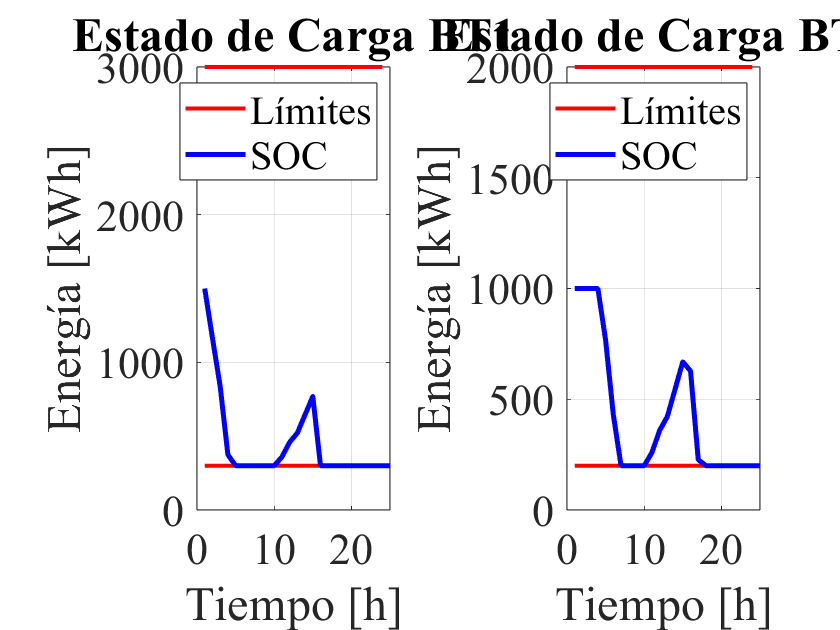

figure % SOC BT1
subplot(1,2,1)
plot(T,S_max1*ones(1,K),'color','r','LineWidth',2)
hold on
plot(T,S_min1*ones(1,K),'color','r','LineWidth',2)
plot(1:K+1,SOC1,'b','LineWidth',2.5)
xlabel('Tiempo [h]','fontsize',24); ylabel('Energía [kWh]','fontsize',24)
title('Estado de Carga BT1','fontsize',24)
grid on
set(gca,'Fontname','Times New Roman','FontSize',22)
legend('Límites','','SOC')


%figure %SOC BT2
subplot(1,2,2)
plot(T,S_max2*ones(1,K),'color','r','LineWidth',2)
hold on
plot(T,S_min2*ones(1,K),'color','r','LineWidth',2)
plot(1:K+1,SOC2,'b','LineWidth',2.5)
xlabel('Tiempo [h]','fontsize',24); ylabel('Energía [kWh]','fontsize',24)
title('Estado de Carga BT2','fontsize',24)
grid on
set(gca,'Fontname','Times New Roman','FontSize',22)
legend('Límites','','SOC')

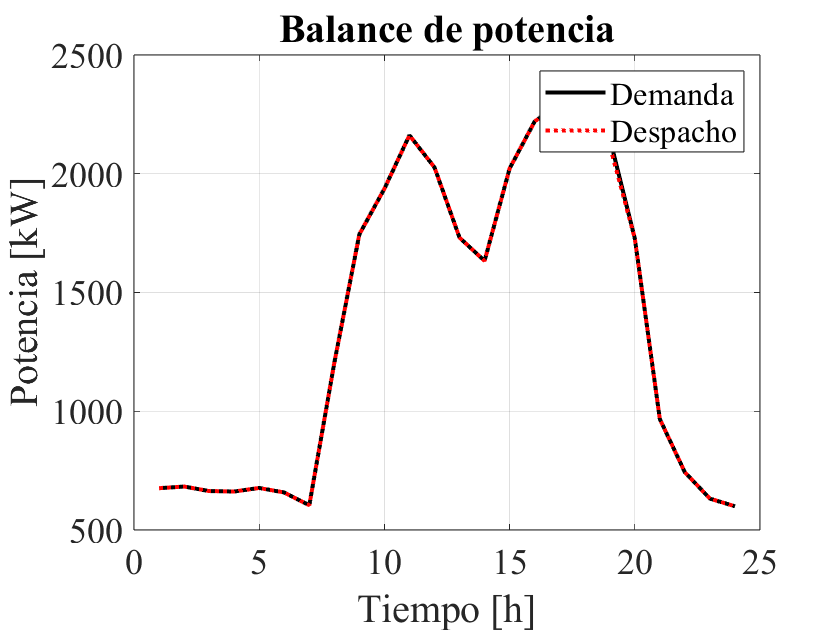








PG = PGD+PBT2+PBT1+PGEOMax'+PpvMax'; % Potencia total generada 
figure %Balance de potencia
T = 1:24;
plot(T,PL,'k',T,PG,'r:','LineWidth',2); hold on
xlabel('Tiempo [h]','fontsize',20);ylabel('Potencia [kW]','fontsize',20);legend('Demanda','Despacho')
title('Balance de potencia','fontsize',20);set(gca,'Fontname','Times New Roman','FontSize',18);grid on

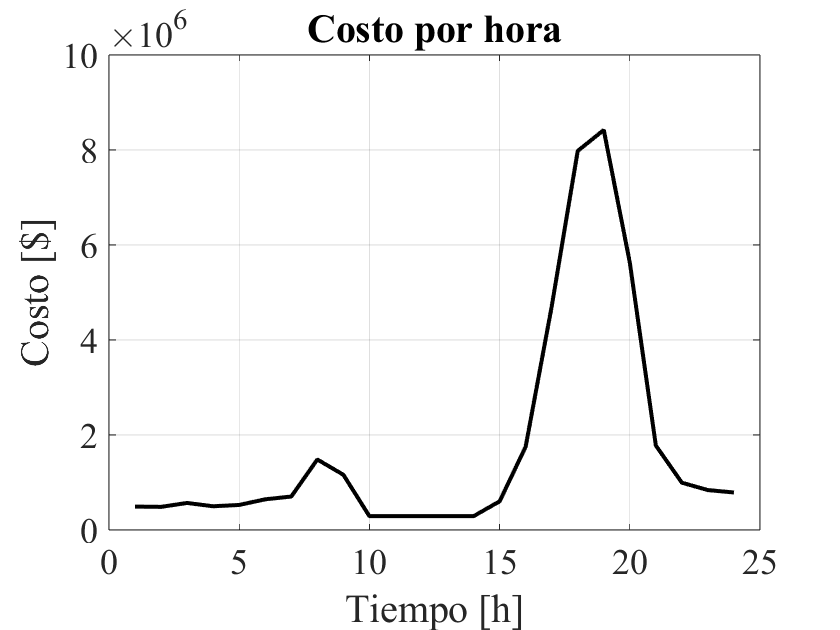



figure % Costos
T = 1:24;
plot(T,fval,'-k','LineWidth',2); hold on
xlabel('Tiempo [h]','fontsize',20);ylabel('Costo [$]','fontsize',20);
title('Costo por hora','fontsize',20);set(gca,'Fontname','Times New Roman','FontSize',18);grid on